## **Przetwarzanie Sygnałów Cyfrowych**

# Analiza harmoniczna cz. 1

## Jan Rosa 410269 AiR

#### Zad 1

 Używajżc polecenia plot, za pomocą zczerwonego kółka oznacz na wykresie punkty zmiany znaku wartości sygnału - wykres umieść w sprawozdaniu.

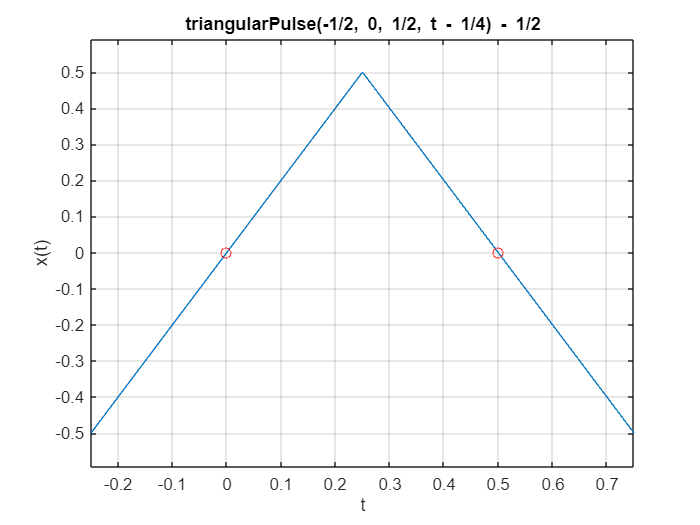

clear all; close all;

syms t t1 t2 offset x 

T0 = 1.0;		% okres
t1 = -0.5; 
t2 = t1+T0;
offset = T0/4;

f0 = 1/T0;		% czestotliwosc
w0 = 2*pi*f0;	% pulsacja

% granice ca³kowania
BND = [t1,t2] + offset; 

x = triangularPulse(t1,0,t2,t-offset)-0.5;
figure; 
ezplot(x,BND); grid on; ylabel('x(t)')
hold on
plot([0, 0.5], 0, 'or')

#### Zad 2

Wyznacz współczynniki zespolonego szeregu Fouriera Xn dla 16-tu pierwszych funkcji

bazowych i oznacz ich wartości na wykresie. W sprawozdaniu umieść uzyskany wykres

zespolonych współcznników szeregu Fouriera.

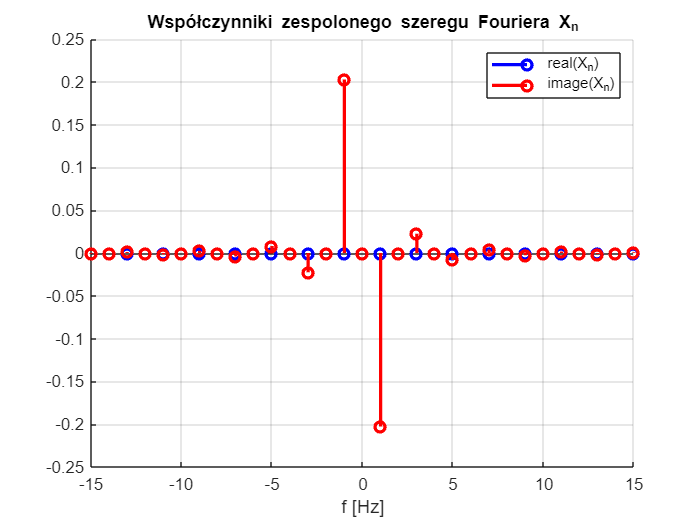

NT = 15;
X=(31);
ind = -NT : NT;
for n = ind
    Xn = (1/T0)*int(x*exp(-i*w0*n*t),t,BND);
    X(n + NT + 1) = Xn;
end
									
figure; hold on; 
stem(ind*f0,real(X),'b','LineWidth',2); 
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2); 
grid on
legend('real(X_n)','image(X_n)','Location','NorthEast')
title('Współczynniki zespolonego szeregu Fouriera X_n')

#### Zad 3

a = 1

a = 1

step = (BND(2) - BND(1))/1000;

Unrecognized function or variable 'BND'.

tt = [BND(1)-T0 : step: BND(2) + T0];
xx = zeros(1,length(tt));
xx =  xx + a(1); % skladowa stala
				
figure
plot(tt,xx,'m'); grid on, hold on;
plot([0,0],[-0.6,0.6],'w.')
xlabel('t'); ylabel('x(t)'); 
pause(0.5)
				
for n = 1 : NT
    xx_n = 2*(a(n+1)*cos(w0*n*tt) + b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r'); plot(tt,xx,'m');
    title(sprintf('n = %d',n+1)); pause(0.5)
end

plot(tt,xx,'k','LineWidth',3);
title('Rekonstrukcja sygna³u ci¹g³ego na podstawie szeregu Fouriera')
